syms S E I R u 
B=0.0001; %B
d=0.0001; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_
nu=0.001; %nu_

y_1 = B + (nu*R) - ((beta+u)*I)*S - d*S ==0

$$y\_1 = \frac{R}{1000}-\frac{S}{10000}-\text{I}\,S\,\left(u+\frac{1}{5}\right)+\frac{1}{10000}=0$$

y_2 = ((beta+u)*I)*S- alpha*E- d*E ==0

$$y\_2 = \text{I}\,S\,\left(u+\frac{1}{5}\right)-\frac{1001\,\text{E}}{10000}=0$$

y_3 = alpha*E - gamma*I - d*I ==0

$$y\_3 = \frac{\text{E}}{10}-\frac{1001\,\text{I}}{10000}=0$$

y_4 = gamma*I - nu*R - d*R ==0

$$y\_4 = \frac{\text{I}}{10}-\frac{11\,R}{10000}=0$$


eq=[y_1,y_2,y_3,y_4]

$$eq = \left(\begin{array}{cccc} \frac{R}{1000}-\frac{S}{10000}-\text{I}\,S\,\left(u+\frac{1}{5}\right)+\frac{1}{10000}=0 & \text{I}\,S\,\left(u+\frac{1}{5}\right)-\frac{1001\,\text{E}}{10000}=0 & \frac{\text{E}}{10}-\frac{1001\,\text{I}}{10000}=0 & \frac{\text{I}}{10}-\frac{11\,R}{10000}=0 \end{array}\right)$$

var=[S,E,I,R]

$$var = \left(\begin{array}{cccc} S & \text{E} & \text{I} & R \end{array}\right)$$


sol=solve(eq,var)

sol = struct with fields:
    S: [2×1 sym]
    E: [2×1 sym]
    I: [2×1 sym]
    R: [2×1 sym]


yj_1= B+(nu*R)-((beta+u)*I)*S-d*S

$$yj\_1 = \frac{R}{1000}-\frac{S}{10000}-\text{I}\,S\,\left(u+\frac{1}{5}\right)+\frac{1}{10000}$$

yj_2=((beta+u)*I)*S-alpha*E-d*E

$$yj\_2 = \text{I}\,S\,\left(u+\frac{1}{5}\right)-\frac{1001\,\text{E}}{10000}$$

yj_3=alpha*E-gamma*I-d*I

$$yj\_3 = \frac{\text{E}}{10}-\frac{1001\,\text{I}}{10000}$$

yj_4=gamma*I-nu*R-d*R

$$yj\_4 = \frac{\text{I}}{10}-\frac{11\,R}{10000}$$


Meq=[yj_1;yj_2;yj_3;yj_4]

$$Meq = \left(\begin{array}{c} \frac{R}{1000}-\frac{S}{10000}-\text{I}\,S\,\left(u+\frac{1}{5}\right)+\frac{1}{10000}\\ \text{I}\,S\,\left(u+\frac{1}{5}\right)-\frac{1001\,\text{E}}{10000}\\ \frac{\text{E}}{10}-\frac{1001\,\text{I}}{10000}\\ \frac{\text{I}}{10}-\frac{11\,R}{10000} \end{array}\right)$$


A_j=jacobian(Meq,var)

$$A\_j = \left(\begin{array}{cccc} -\text{I}\,\left(u+\frac{1}{5}\right)-\frac{1}{10000} & 0 & -S\,\left(u+\frac{1}{5}\right) & \frac{1}{1000}\\ \text{I}\,\left(u+\frac{1}{5}\right) & -\frac{1001}{10000} & S\,\left(u+\frac{1}{5}\right) & 0\\ 0 & \frac{1}{10} & -\frac{1001}{10000} & 0\\ 0 & 0 & \frac{1}{10} & -\frac{11}{10000} \end{array}\right)$$

B_j=jacobian(Meq,u)

$$B\_j = \left(\begin{array}{c} -\text{I}\,S\\ \text{I}\,S\\ 0\\ 0 \end{array}\right)$$

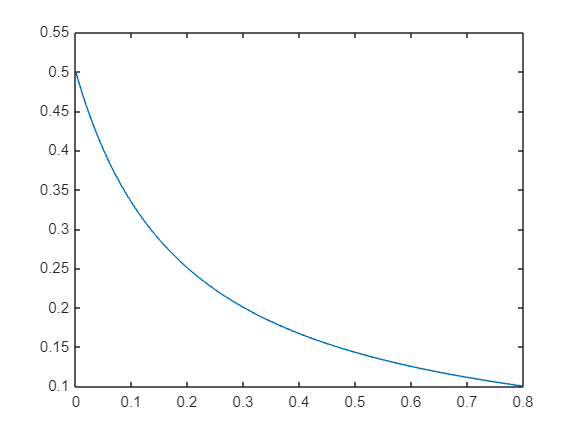

u_aux=0:0.001:0.8;
S_aux=zeros(1,numel(u_aux));
E_aux=zeros(1,numel(u_aux));
I_aux=zeros(1,numel(u_aux));
R_aux=zeros(1,numel(u_aux));
for i=1:numel(u_aux)
    S_aux(i)=double(subs(sol.S(2),u,u_aux(i)));
    E_aux(i)=double(subs(sol.E(2),u,u_aux(i)));
    I_aux(i)=double(subs(sol.I(2),u,u_aux(i)));
    R_aux(i)=double(subs(sol.R(2),u,u_aux(i)));
end
pe=[u_aux' S_aux' E_aux' I_aux' R_aux'];
plot(u_aux,S_aux)

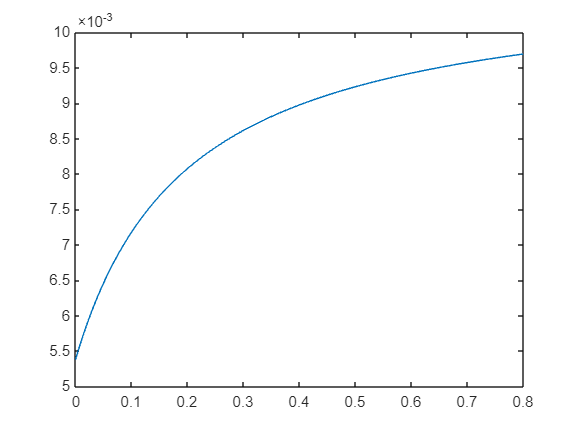

plot(u_aux,E_aux)

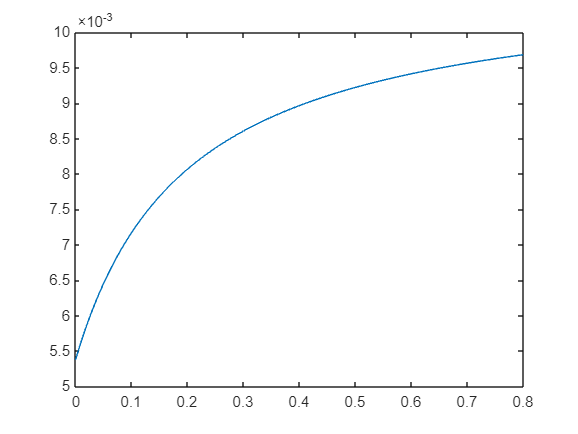

plot(u_aux,I_aux)

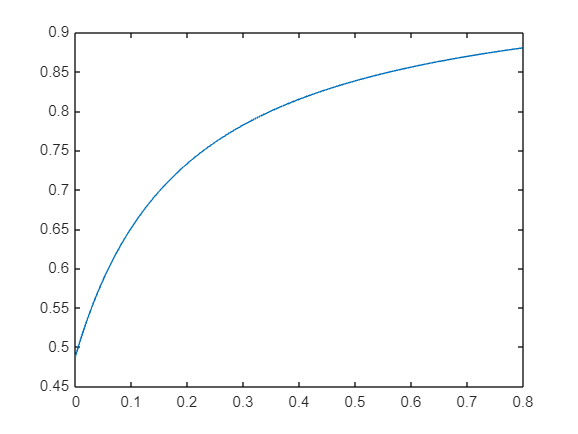

plot(u_aux,R_aux)

x=zeros(1,6);
x(1)=0.0001; %B
x(2)=0.0001; %d
x(3)=0.1; %alpha_
x(4)=0.1; %gamma_
x(5)=0.2; %beta_
x(6)=0.001;

i = 601

valores_u=0.1:0.1:0.8;
u_tabla=zeros(1,8)

u_tabla =      0     0     0     0     0     0     0     0


rango_tabla=zeros(1,8)

rango_tabla =      0     0     0     0     0     0     0     0


condicion_tabla=zeros(1,8)

condicion_tabla =      0     0     0     0     0     0     0     0


x_tabla=zeros(8,4)

for i=1:8
    idx=find(abs(u_aux-valores_u(i)) < 0.001/2);
    u0 = pe(idx,1);
    x0 = [pe(idx,2) pe(idx,3) pe(idx,4) pe(idx,5)];
    [A,B,C,D] = linmod('SEIRS_3',x0,u0);
    S = ss(A,B,C,D);
    Mc=[B A*B A^2*B A^3*B];
    x_tabla(i,1:end)=x0;
    u_tabla(i)=u0;
    rango_tabla(i)=rank(Mc);
    condicion_tabla(i)=cond(Mc);
end


table(u_tabla',x_tabla,rango_tabla',condicion_tabla',VariableNames={'u','x','Rango Mc','Num condicion Mc'})

ans = 8×4 table
     u                           x                           Rango Mc    Num condicion Mc
    ___    ______________________________________________    ________    ________________

    0.1      0.334    0.0071754    0.0071682      0.65166       3            1.805e+18   
    0.2     0.2505     0.008075    0.0080669      0.73336       3           1.4392e+18   
    0.3     0.2004    0.0086148    0.0086062      0.78238       3           3.2728e+18   
    0.4      0.167    0.0089746    0.0089657      0.81506       3           1.2011e+18   
    0.5    0.14314    0.0092317    0.0092224       0.8384       3           1.2422e+19   
    0.6    0.12525    0.0094244     0.009415      0.85591       3           2.2652e+19   
    0.7    0.11133    0.0095744    0.0095648      0.86953       3           1.9845e+18   
    0.8     0.1002    0.0096943    0.